## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
 file_path = "20MHz_USRP.json";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 2027.17 m/s
	 Velocity Resolution 		 31.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


### Initialize the target

target_pos = 100;
target_vel = -5;
simulator.load_target_realistic(target_pos,target_vel);

### Initialize the Victim and Simulation Parameters

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

### Initialize the Attacker

%initialize the attacker
%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,1);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

attack_type = "velocity spoof - similar velocity";
desired_pos = 75;
desired_vel = 7;
%attack_type = "velocity spoof - similar velocity,range spoof - similar slope ";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
if attack_type == "target"
    simulator.Attacker.Subsystem_attacking.set_desired_attack_location(desired_pos,desired_vel);
end

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path);

### Plot Tx Chirp to confirm correctness

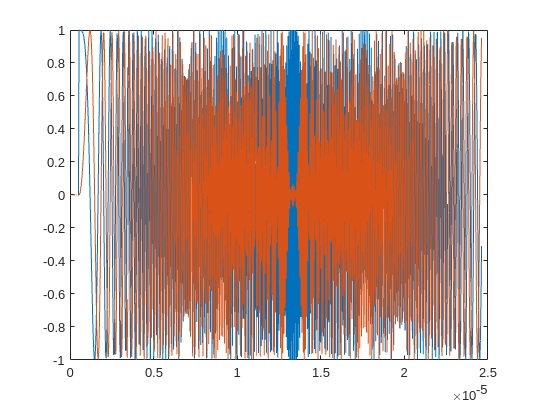

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

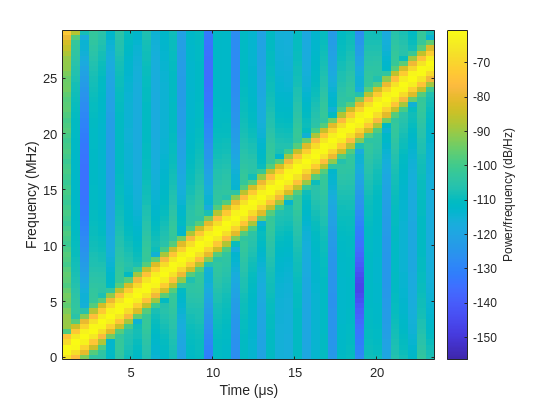

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Run simulation if desired to compare results

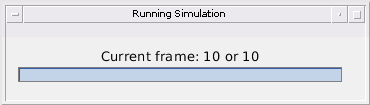

%run the simulation (without an attacker for now)
frames_to_compute = 10;
simulator.run_simulation_with_attack(frames_to_compute,true);

## RUN EXPERIMENT ON USRP DEVICE - SENSING ONLY

## [Optional] Get sensing system received signal from USRP device

## Verify C++ computations

### Spectrogram Generation

#### Get key initialization parameters

%print key properties for spectrum subsystem
num_rows = size(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal,2);
samples_per_sampling_window = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.num_samples_per_sampling_window;
fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
samp_freq = simulator.Attacker.FMCW_sample_rate_Msps * 1e6;

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

 rows: 986 
 samples per sampling window: 60 
 fft size: 32 
 samp freq: 2.953600e+07

#### Verify Hanning Window

%get the hanning window
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true,"float");

%compare with the computed hanning window
compare = all(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.window) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

Hanning window matches

#### Reshaped and windowed Received Signal - save received signal to file

%print the number of received samples
received_samples = size(simulator.Attacker.Subsystem_spectrum_sensing.received_signal,2);
fprintf(" receieved_samples: %d\n",received_samples)

 receieved_samples: 0


#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

%compare with the computed hanning window

% compare = all(abs(read_data_reshaped - simulator.Attacker.Subsystem_spectrum_sensing.windowed_signal) < 1e-5);
% 
% if compare
%     fprintf("Reshaped and windowed signal for fft matches")
% else
%     fprintf("Reshaped and windowed signal for fft doesn't match")
% end

#### Generated Spectrogram

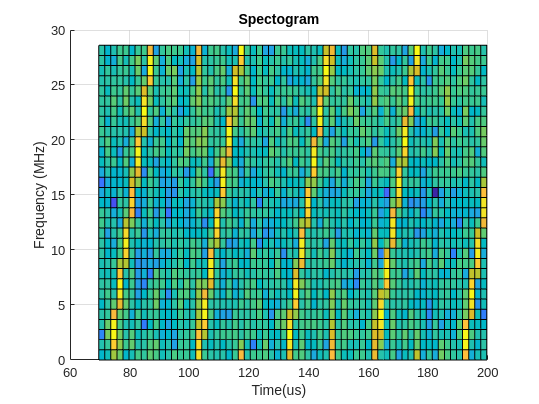

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);
times = simulator.Attacker.Subsystem_spectrum_sensing.plot_params.times;
frequencies = simulator.Attacker.Subsystem_spectrum_sensing.plot_params.frequencies;

max_time_to_plot_us = 200;
idx_to_plot = times < max_time_to_plot_us;

clf;
surf(times(idx_to_plot),...
    frequencies,...
    read_data_reshaped(:,idx_to_plot));
title_str = sprintf('Spectogram');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

#### Detected Times and Frequencies - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_frequencies.bin";

read_data_detected_frequencies = simulator.read_from_file(path,false,"float");

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_times.bin";
read_data_detected_times = simulator.read_from_file(path,false,"float");

#### Clusters - read and verify

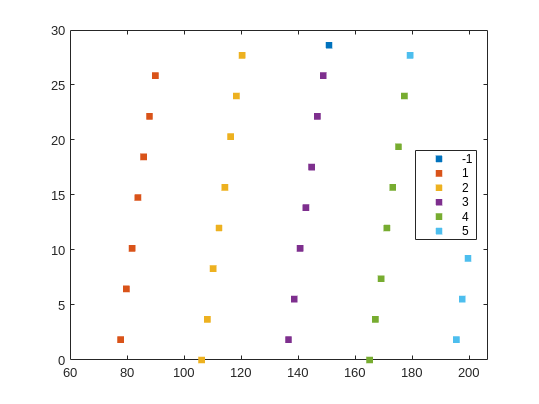

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_clusters.bin";
read_data = simulator.read_from_file(path,false,"int");
read_data_idx = read_data(read_data ~= 0);

max_time_to_plot_us = 200;
idx_to_plot = read_data_detected_times < max_time_to_plot_us;

gscatter(read_data_detected_times(idx_to_plot), ...
    read_data_detected_frequencies(idx_to_plot), ...
    read_data_idx(idx_to_plot));

#### Computed Linear Models

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_slopes.bin";
read_data_detected_slopes = simulator.read_from_file(path,false,"float")

read_data_detected_slopes =     1.9640
    1.9639
    1.9801
    1.9803
    1.9634
    1.9630




path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_intercepts.bin";
read_data_intercepts = simulator.read_from_file(path,false,"float")

read_data_intercepts =    72.5716
  102.0982
  131.6665
  161.2022
  190.6445
  220.3711


#### Captured Frames Array

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_captured_frames.bin";
read_data = simulator.read_from_file(path,false,"float");
read_data = reshape(read_data,6,[]).'

read_data = 1.0e+05 *

         0    0.0004    0.0000    0.0005    2.5001         0
    0.3333    0.0004    0.0000    0.0005    2.8334    3.1667
    0.3333    0.0004    0.0000    0.0005    3.1667    3.5000
    0.3333    0.0004    0.0000    0.0005    3.5000    3.8333
    0.3333    0.0004    0.0000    0.0005    3.8333    4.1666
    0.3333    0.0004    0.0000    0.0005    4.1666    4.4999
    0.3333    0.0004    0.0000    0.0005    4.4999    4.8332


estimation_errors = read_data(2:end - 1,6) - read_data(3:end,5)

estimation_errors =     1.3438
    1.3750
   -1.1562
    1.1562
    0.9688


### Get the estimated parameters

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_estimated_parameters_2.bin";
read_data = simulator.read_from_file(path,false,"float");
estimated_frame_duration_ms = read_data(1);
estimated_chirp_duration_us = read_data(2);
estimated_chirp_slope_MHz_us = read_data(3);

% %print out the relevant information
fprintf("Average Frame Duration: %3.7f ms",estimated_frame_duration_ms);

Average Frame Duration: 0.0000000 ms

fprintf("Average Chirp Duration: %3.3f us",estimated_chirp_duration_us);

Average Chirp Duration: 29.539 us

fprintf("Average Slope: %1.3f MHz/us",estimated_chirp_slope_MHz_us);

Average Slope: 1.961 MHz/us

### Reset simulation and compute attack chirp

%reset locations
simulator.load_usrp_attacker_and_victim_position_and_velocity();
simulator.load_target_realistic(target_pos,target_vel);

current_frame = 1;
num_samples_sent = 1;
[victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = ...
                    simulator.FMCW_determine_positions_and_velocities(...
                    current_frame,num_samples_sent);
simulator.Attacker.update_victim_pos_and_velocity(attacker_pos,victim_pos,attacker_vel, victim_vel);
simulator.Attacker.update_target_pos_and_velocity(victim_pos, tgt_pos, victim_vel,tgt_vel);
simulator.Attacker.Subsystem_attacking.frame = 1;

%send configuration to the attacker

simulator.Attacker.Subsystem_attacking.compute_calculated_values( ...
    estimated_chirp_duration_us, ...
    estimated_chirp_slope_MHz_us, ...
    estimated_frame_duration_ms, ...
    256);

simulator.Attacker.Subsystem_attacking.compute_next_emulated_chirps();

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_attacking_chirps_full.bin";

%get the eumulated chirps
write_data = simulator.Attacker.Subsystem_attacking.emulated_chirps;

%reshape to be able to send to a file
write_data = reshape(write_data,[],1);
simulator.save_to_file(write_data,path);

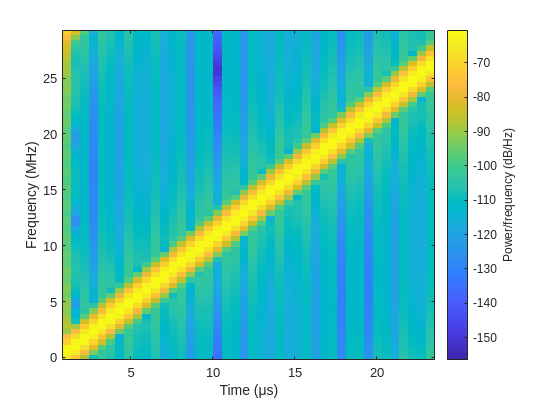

attack_chirp = simulator.Attacker.Subsystem_attacking.emulated_chirps(:,1);
spectrogram(attack_chirp,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN ATTACK ON MATLAB

### Read Rx data from MATLAB

path = "/home/david/Documents/MATLAB_generated/cpp_rx_data_files/cpp_rx_data.bin";
read_data = simulator.read_from_file(path,true,"float");

num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);

%determine the number of frames recorded
num_frames = size(read_data,3);

### Plot Rx Chirp to confirm correctness

Specify chirp:

chirp =3;

Specify frame:

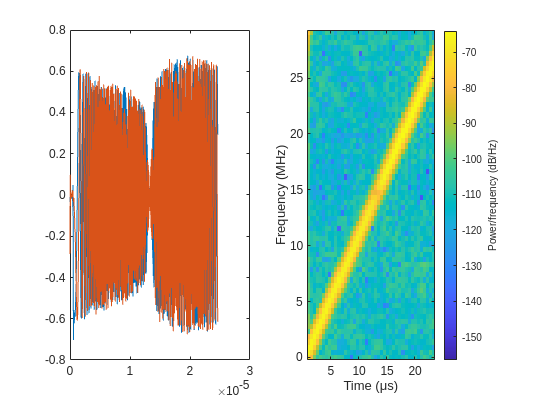

frame = 8;
% the chirp signal
%chirp = 251;
%frame = 20;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
subplot(1,2,1);
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))
subplot(1,2,2)
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Process received Rx Signal

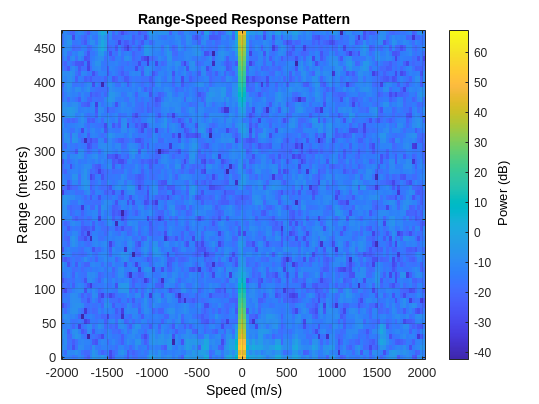

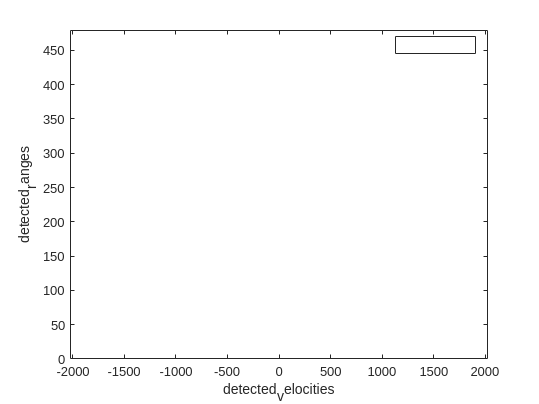

%specify the number of frames and chirps to compute
clf;
frames_to_compute = size(read_data,3);
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
simulator.Victim.precompute_radar_chirps();


F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
    
    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = read_data(:,chirp,frame);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %CA CFAR 2-D
    detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(...
        abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    
    
    %estimate the range and the velocities
    if ~isempty(detections)
    
        %DBSCAN Clustering
        idx = dbscan(detections.',...
            simulator.Victim.Radar_Signal_Processor.Epsilon,...
            simulator.Victim.Radar_Signal_Processor.minpts);
    
        %plot the range-doppler and clustering responses
        
        %plot range doppler
        plotResponse( ...
            simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
            radar_cube);
        drawnow
        F_rngdop(frame) = getframe(gcf);
    
        %plot the clusters
        gscatter(detected_velocities,detected_ranges,idx);
        axis([-1 * ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            0,simulator.Victim.Radar_Signal_Processor.Radar.Range_Max_m]);
        drawnow
        F_clusters(frame) = getframe(gcf);
    else
        %plot range doppler
        plotResponse( ...
            simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
            radar_cube);
        drawnow
        F_rngdop(frame) = getframe(gcf);
    
    
        %plot the clusters
        clf;
        detected_velocities = [0];
        detected_ranges = [0];
        idx = [1];
        gscatter(detected_velocities,detected_ranges,idx);
        axis([-1 * ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            simulator.Victim.Radar_Signal_Processor.Radar.V_Max_m_per_s, ...
            0,simulator.Victim.Radar_Signal_Processor.Radar.Range_Max_m]);
        cla;
        drawnow
        F_clusters(frame) = getframe(gcf);
    end
end

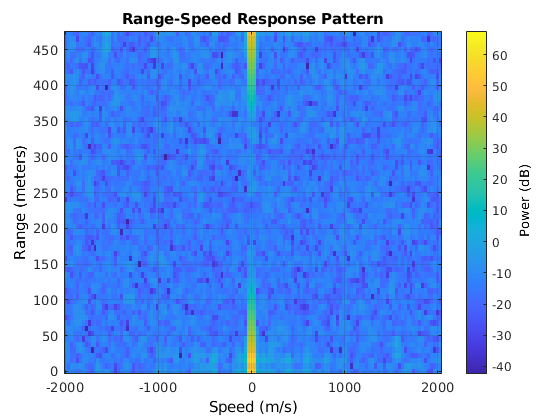

%play the range doppler movie for the output
clf;
fig = figure;
movie(fig,F_rngdop,1,10);

clf;
fig = figure;
movie(fig,F_clusters,1,10);

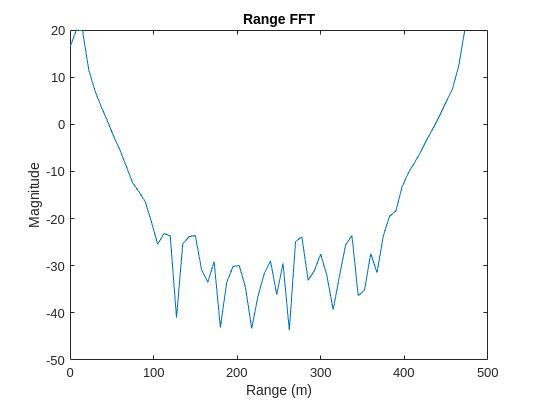

window = hann(simulator.Victim.ADC_Samples);
windowed_sig = window .* radar_cube(:,1);
range_fft = 20 * log10(abs(fft(windowed_sig)));
clf;
plot(simulator.Victim.Ranges,range_fft)
xlabel("Range (m)");
ylabel("Magnitude");
title("Range FFT")

## Code to align the rx and the tx signal using cross correlation

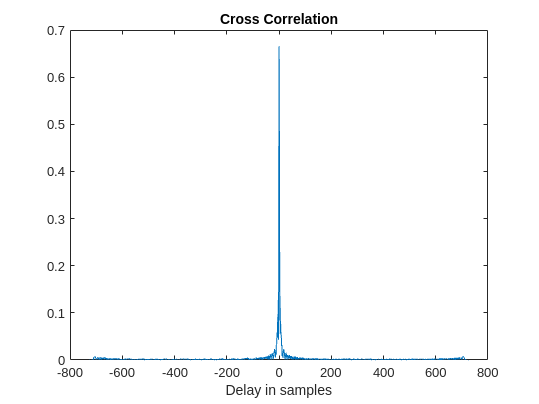

[C,lag] = xcorr(Rx_sig,Tx_sig,"normalized");
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")

[M,I] = max(abs(C));
delay_samps = lag(I)

delay_samps = 0

delay_us = delay_samps * simulator.Victim.FMCW_sampling_period_s * 1e6

delay_us = 0

% plot(lag,C,[t21 t21],[-0.5 1],'r:')
% text(t21+100,0.5,['Lag: ' int2str(t21)])
% ylabel('C_{21}')